# Chapter 3

## Explanatory Data Analysis and Pivot Tables

Xt= readtable("Firm.xlsx", ReadRowNames=true)

Xt = 107×9 table
                Surname             Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    _________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0211    {'BASILICO' }    {'TIZIANA'      }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    P0212    {'BONINO'   }    {'PAOLO'        }    {'M'}     01-Jul-1993      {'B'}      2375         35                12              8    
    P0213    {'GRI'      }    {'ALBERTO'      }    {'M'} 

t1=summary(Xt(:,1:6))

t1 = struct with fields:
      Surname: [1×1 struct]
         Name: [1×1 struct]
       Gender: [1×1 struct]
    BirthDate: [1×1 struct]
    Education: [1×1 struct]
         Wage: [1×1 struct]


t2=summary(head(Xt,6))

t2 = struct with fields:
           Surname: [1×1 struct]
              Name: [1×1 struct]
            Gender: [1×1 struct]
         BirthDate: [1×1 struct]
         Education: [1×1 struct]
              Wage: [1×1 struct]
     CommutingTime: [1×1 struct]
    SmartWorkHours: [1×1 struct]
         Seniority: [1×1 struct]


% Display the summaries in the command window
disp(t1);

      Surname: [1×1 struct]
         Name: [1×1 struct]
       Gender: [1×1 struct]
    BirthDate: [1×1 struct]
    Education: [1×1 struct]
         Wage: [1×1 struct]



disp(t2);

           Surname: [1×1 struct]
              Name: [1×1 struct]
            Gender: [1×1 struct]
         BirthDate: [1×1 struct]
         Education: [1×1 struct]
              Wage: [1×1 struct]
     CommutingTime: [1×1 struct]
    SmartWorkHours: [1×1 struct]
         Seniority: [1×1 struct]



% Create a summary table for the entire dataset
summaryTable = summary(Xt);
disp(summaryTable);

           Surname: [1×1 struct]
              Name: [1×1 struct]
            Gender: [1×1 struct]
         BirthDate: [1×1 struct]
         Education: [1×1 struct]
              Wage: [1×1 struct]
     CommutingTime: [1×1 struct]
    SmartWorkHours: [1×1 struct]
         Seniority: [1×1 struct]



colors = categorical(["green" "blue" "red"])

colors = 1×3 categorical array
     green      blue      red 


disp(colors)

     green      blue      red 



% create a catagorical order for those who doesn't have manually
rankm= categorical(["first" "third" "second"],["first" "second" "third"])

rankm = 1×3 categorical array
     first      third      second 


% create a string array of length 10 named c
c= string(["School leaving certficate","High school graduate","Bachlor Degree", "Masters Degree"]);

% now convert the above c to ordinal catagorical
% Convert the string array to a categorical array with ordinal categories
cat = categorical(c, 'Ordinal', true);

levels=(["School leaving certficate","High school graduate","Bachlor Degree", "Masters Degree"])

levels = 1×4 string array
    "School leaving certficate"    "High school graduate"    "Bachlor Degree"    "Masters Degree"


cat2 = categorical(c,levels,Ordinal=true)

cat2 = 1×4 categorical array
     School leaving certficate      High school graduate      Bachlor Degree      Masters Degree 


cat2 =addcats(cat2,"Primary School","Before","School leaving certficate")

cat2 = 1×4 categorical array
     School leaving certficate      High school graduate      Bachlor Degree      Masters Degree 


cat2 = addcats(cat2,'Phd Degree','After','Masters Degree')

cat2 = 1×4 categorical array
     School leaving certficate      High school graduate      Bachlor Degree      Masters Degree 


% Display the updated categorical array
disp(cat2);

     School leaving certficate      High school graduate      Bachlor Degree      Masters Degree 



% define gender as nominal catagorical
Xt.Gender = categorical(Xt.Gender);
% define educational as ordinal catagory
Xt.Education= categorical(Xt.Education, Ordinal=true);

## Univariate Analysis of Categorical Variables

## frequency distribution


tabulate(Xt.Education)

  Value    Count   Percent
      A       24     22.43%
      B       37     34.58%
      C       46     42.99%



tabulate(Xt.Gender)

  Value    Count   Percent
      F       46     42.99%
      M       61     57.01%



tabulate(Xt.Wage)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3        0      0.00%
      4        0      0.00%
      5        0      0.00%
      6        0      0.00%
      7        0      0.00%
      8        0      0.00%
      9        0      0.00%
     10        0      0.00%
     11        0      0.00%
     12        0      0.00%
     13        0      0.00%
     14        0      0.00%
     15        0      0.00%
     16        0      0.00%
     17        0      0.00%
     18        0      0.00%
     19        0      0.00%
     20        0      0.00%
     21        0      0.00%
     22        0      0.00%
     23        0      0.00%
     24        0      0.00%
     25        0      0.00%
     26        0      0.00%
     27        0      0.00%
     28        0      0.00%
     29        0      0.00%
     30        0      0.00%
     31        0      0.00%
     32        0      0.00%
     33        0      0.00%
     34        0      0.00%
     35        0     


tabulate(Xt.Seniority)

  Value    Count   Percent
      1        3      2.80%
      2        9      8.41%
      3        3      2.80%
      4        3      2.80%
      5        4      3.74%
      6        2      1.87%
      7        5      4.67%
      8        4      3.74%
      9        3      2.80%
     10        4      3.74%
     11        5      4.67%
     12        4      3.74%
     13        4      3.74%
     14        5      4.67%
     15        4      3.74%
     16        7      6.54%
     17        3      2.80%
     18        2      1.87%
     19        4      3.74%
     20        2      1.87%
     21        0      0.00%
     22        1      0.93%
     23        1      0.93%
     24        2      1.87%
     25        1      0.93%
     26        2      1.87%
     27        0      0.00%
     28        3      2.80%
     29        1      0.93%
     30        2      1.87%
     31        5      4.67%
     32        2      1.87%
     33        1      0.93%
     34        1      0.93%
     35        1     

mode(Xt.Gender)

ans = categorical
     M 


tabulate(Xt.Gender)

  Value    Count   Percent
      F       46     42.99%
      M       61     57.01%


median(Xt.Education)

ans = categorical
     B 


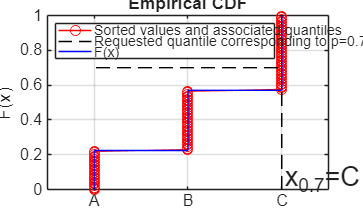

ans = struct with fields:
    quantile: 'C'


% COMPUte and display in plot the 0.7 quantile for the ordinal catagorical
% variable education
GUIquantile(Xt.Education,0.7)

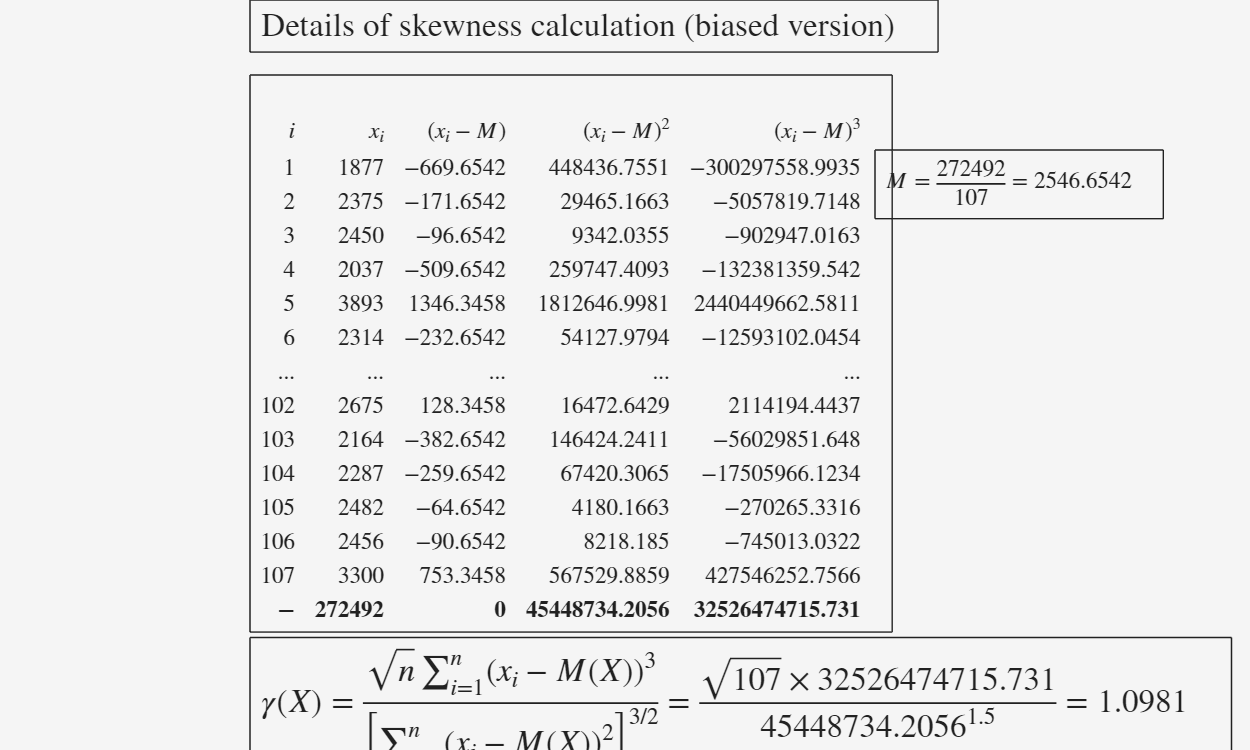

ans = struct with fields:
     data: [108×5 table]
    gamma: 1.0981


GUIskewness(Xt.Wage)

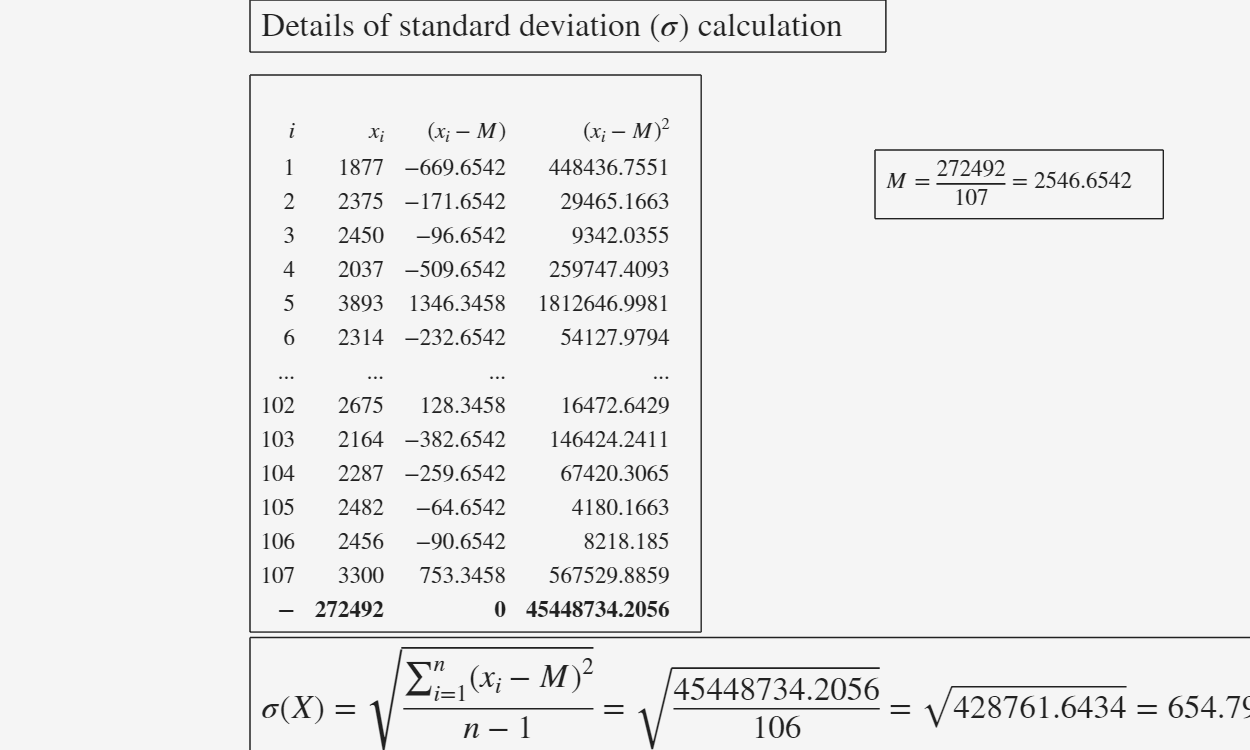

ans = struct with fields:
    data: [108×4 table]
     std: 654.7989


GUIstd(Xt.Wage)

Xdg=([Xt.Wage Xt.CommutingTime Xt.SmartWorkHours  Xt.Seniority])

Xdg =         1877          27          10          11
        2375          35          12           8
        2450          39          16          11
        2037          16           6           7
        3893          23           8          30
        2314          29          10          23
        1893          29           6          12
        2443          16           6          28
        2016          19           4           2
        1635          45          16           2
        2593          15           4          13
        3370          26          12          16
        2141          27          10           6
        4354          21          10          40
        2226          47          14          11


% calculate the mean and median of all four variable of Xdg
meanvalue= mean(Xdg)

meanvalue = 1.0e+03 *

    2.5467    0.0224    0.0076    0.0153


medianv=median(Xdg)

medianv =         2423          20           6          14


Xdq =[ "Wage" "CommutingTime"  "SmartWorkHours"  "Seniority" ]

Xdq = 1×4 string array
    "Wage"    "CommutingTime"    "SmartWorkHours"    "Seniority"


Xdq2=Xt(:,Xdq)

Xdq2 = 107×4 table
             Wage    CommutingTime    SmartWorkHours    Seniority
             ____    _____________    ______________    _________

    P0211    1877         27                10             11    
    P0212    2375         35                12              8    
    P0213    2450         39                16             11    
    P0214    2037         16                 6              7    
    P0215    3893         23                 8             30    
    P0216    2314         29                10             23    
    P0217    1893         29                 6             12    
    P0218    2443         16                 6             28    
    P0219    2016         19   

mean(Xdq2)

ans = 1×4 table
     Wage     CommutingTime    SmartWorkHours    Seniority
    ______    _____________    ______________    _________

    2546.7       22.355            7.5888         15.262  


median(Xdq2)

ans = 1×4 table
    Wage    CommutingTime    SmartWorkHours    Seniority
    ____    _____________    ______________    _________

    2423         20                6              14    


std(Xdg)

ans =   654.7989    8.8651    3.2707   10.5234


std(Xdq2)

ans = 1×4 table
    Wage     CommutingTime    SmartWorkHours    Seniority
    _____    _____________    ______________    _________

    654.8       8.8651            3.2707         10.523  


% calculate coefficient variation 
cv = std(Xdg) ./ meanvalue * 100; % Calculate coefficient of variation
disp('Coefficient of Variation:');

Coefficient of Variation:


disp(cv);

   25.7121   39.6557   43.0986   68.9532



% compute skewness
skewness(Xdg,0)

ans =     1.1138    0.9890    0.8261    0.6682


skewness(Xdq2)

ans = 1×4 table
     Wage     CommutingTime    SmartWorkHours    Seniority
    ______    _____________    ______________    _________

    1.0981       0.97506          0.81443         0.65881 



% compute kurtosis
kurtosis(Xdg)

ans =     3.7885    3.7216    2.9839    2.5635


kurtosis(Xdq2)

ans = 1×4 table
     Wage     CommutingTime    SmartWorkHours    Seniority
    ______    _____________    ______________    _________

    3.7885       3.7216            2.9839         2.5635  


## Univariate plots for Categorical or Quantitative Data

histogram(Xt.Education);
xlabel("Education");
title("Education");
legend("show");

piechart(Xt.Gender);
title("Gender");
legend("show");

rng(100)
n=1000
x=randn(n,1)
bins=[-inf;-2;0;1.5;inf]
h=histogram(n,bins)

Y= readtable("Firm.xlsx",ReadRowNames=true)

% construct boxplot of the wage variable for all observation (first
% vertical panal
boxplot(Y.Wage);
ylabel('Wage');
title('Boxplot of Wage Variable');

% and now separtatly for men and women (second vertical panal)


subplot(2,2,1);
% using FSDA tool box
boxplot(Y.Wage);
subplot(2,2,2);
boxplot(Y.Wage,Y.Gender);
subplot(2,2,3);
boxplot(Y.Wage,Y.Gender);

% compute the quantiles x0.10,x0.15,.....,x0.90 for the wage variable
% separatly for men and women
range=(0.1:0.1:0.9)
qm=Y{Y.Gender=="M","Wage"}
qf=Y{Y.Gender=="F","Wage"}
quantile(qm,range)
% Compute and display the quantiles for the wage variable separately for men and women
quantilesM = quantile(qm, range);
quantilesF = quantile(qf, range);
disp('Quantiles for Men:');
disp(quantilesM);
disp('Quantiles for Women:');
disp(quantilesF);
% now plot the quantile versus wage for male and female
% Plot the quantiles for men and women
figure;
plot(range, quantilesM, '-o', 'DisplayName', 'Men');
hold on;
plot(range, quantilesF, '-o', 'DisplayName', 'Women');
xlabel('Quantile Levels');
ylabel('Wage');
title('Quantiles of Wage by Gender');
legend('show');
hold off;

qr=(0.1:0.1:0.9);
wm = Y{Y.Gender=="M","Wage"};
wf=Y{Y.Gender=="F","Wage"};
quanm=quantile(wm,qr);
quanf = quantile(wf,qr);

plot(qr,quanf,qr,quanm)

## Confidence Interval and Advance Summary

X = readtable("Firm.xlsx",ReadRowNames=true)
% plot the 99% confidence interval for wage variable for each level of
% education using vertical bars. using grpstatus
% Calculate and plot the 99% confidence interval for wage variable for each level of education
educationLevels = categories(Xt.Education);
meanWage = grpstats(Xt.Wage, Xt.Education, 'mean');
stdWage = grpstats(Xt.Wage, Xt.Education, 'std');
nLevels = histcounts(Xt.Education);
% Calculate the 99% confidence intervals
confInterval = 1.96 * (stdWage ./ sqrt(nLevels)); 
lowerBound = meanWage - confInterval;
upperBound = meanWage + confInterval;
% Plot the confidence intervals as vertical bars
figure;

xlabel('Education Level');
ylabel('Mean Wage');
title('99% Confidence Interval for Wage by Education Level');
grid on;







## Pivot Table via the Guided Interface

% Create pivoted table
pivotedData = pivot(Y, Rows="Gender", Columns="Education", DataVariable="Wage", ...
    Method="mean", RowLabelPlacement="rownames")

pivotedData = 2×3 table
           A         B         C   
         ______    ______    ______

    F    2169.5      2356    2710.2
    M    2061.4    2659.6    2846.9


% Create pivoted table
pivotedData2 = pivot(Y, Rows=["Gender","Wage"], RowsBinMethod={"none",2}, ...
    Columns="Education", RowLabelPlacement="rownames")

pivotedData2 = 4×3 table
                      A     B     C 
                      __    __    __

    F_[1000, 3000)    10    13    16
    F_[3000, 5000]     0     2     5
    M_[1000, 3000)    14    16    16
    M_[3000, 5000]     0     6     9


pivot(X,Columns="Education",Rows="Gender")

ans = 2×4 table
    Gender    A     B     C 
    ______    __    __    __

    {'F'}     10    15    21
    {'M'}     14    22    25


pivot(Y,Rows="Gender",RowLabelPlacement="rownames")

ans = 2×1 table
         count
         _____

    F     46  
    M     61  


pivot(Y,Rows="Gender")

ans = 2×2 table
    Gender    count
    ______    _____

    {'F'}      46  
    {'M'}      61  


pivot(Y,Rows="Gender",Columns="Education",RowLabelPlacement="rownames")

ans = 2×3 table
         A     B     C 
         __    __    __

    F    10    15    21
    M    14    22    25


pivot(Y,Rows="Gender",Columns="Education",IncludeTotals=true)

ans = 3×5 table
         Gender          A     B     C     Overall_count
    _________________    __    __    __    _____________

    {'F'            }    10    15    21          46     
    {'M'            }    14    22    25          61     
    {'Overall_count'}    24    37    46         107     


pivot(Y,Rows='Gender',Columns='Education',IncludeTotals=true)

ans = 3×5 table
         Gender          A     B     C     Overall_count
    _________________    __    __    __    _____________

    {'F'            }    10    15    21          46     
    {'M'            }    14    22    25          61     
    {'Overall_count'}    24    37    46         107     


t1=pivot(Y,Rows='Gender',Columns='Education',DataVariable='Wage',Method='mean',IncludeTotals=true)

t1 = 3×5 table
         Gender           A         B         C       Overall_mean
    ________________    ______    ______    ______    ____________

    {'F'           }    2169.5      2356    2710.2       2477.2   
    {'M'           }    2061.4    2659.6    2846.9       2599.1   
    {'Overall_mean'}    2106.5    2536.5    2784.5       2546.7   


pivot(Y,Rows="Gender",Columns="Education",DataVariable="Wage",Method=method,IncludeTotals=true)

ans = 3×5 table
        Gender              A               B               C          Overall_fun 
    _______________    ____________    ____________    ____________    ____________

    {'F'          }    1562    2875    1635    3637    1840    4185    1562    4185
    {'M'          }    1559    2634    1812    4354    1866    4306    1559    4354
    {'Overall_fun'}    1559    2875    1635    4354    1840    4306    1559    4354


pivot(Y,Rows="Wage",Columns="Education",RowsBinMethod=5)

ans = 5×4 table
     disc_Wage      A     B     C 
    ____________    __    __    __

    [1500, 2100)    12    10     7
    [2100, 2700)    11    18    20
    [2700, 3300)     1     4    10
    [3300, 3900)     0     4     3
    [3900, 4500]     0     1     6


X1=X    

X1 = 107×9 table
                Surname             Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    _________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0211    {'BASILICO' }    {'TIZIANA'      }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    P0212    {'BONINO'   }    {'PAOLO'        }    {'M'}     01-Jul-1993      {'B'}      2375         35                12              8    
    P0213    {'GRI'      }    {'ALBERTO'      }    {'M'} 

% modify the first value of wage in x1 to 2000
X1.Wage(1)=2000;

interval=[1500:500:4500]

interval =         1500        2000        2500        3000        3500        4000        4500


pivot(X1,Rows="Wage",Columns="Education",RowsBinMethod=interval)

ans = 6×4 table
     disc_Wage      A     B     C 
    ____________    __    __    __

    [1500, 2000)    10     5     6
    [2000, 2500)    12    15    16
    [2500, 3000)     2     9    10
    [3000, 3500)     0     5     7
    [3500, 4000)     0     2     2
    [4000, 4500]     0     1     5


%right closed bin interval
intervalr=(1500:500:4500)

intervalr =         1500        2000        2500        3000        3500        4000        4500


pivot(X1, Rows="Wage",Columns="Education",RowsBinMethod=intervalr)

ans = 6×4 table
     disc_Wage      A     B     C 
    ____________    __    __    __

    [1500, 2000)    10     5     6
    [2000, 2500)    12    15    16
    [2500, 3000)     2     9    10
    [3000, 3500)     0     5     7
    [3500, 4000)     0     2     2
    [4000, 4500]     0     1     5



pivot(X1,Rows=["Gender" "Education"],Columns="Seniority",ColumnsBinMethod=[0:15:42],IncludeTotals=true)

ans = 7×6 table
         Gender          Education     [0, 15)    [15, 30]    <missing_disc_Seniority>    Overall_count
    _________________    __________    _______    ________    ________________________    _____________

    {'F'            }    {'A'     }       4           4                   2                     10     
    {'F'            }    {'B'     }       8           5                   2                     15     
    {'F'            }    {'C'     }      12           6                   3                     21     
    {'M'            }    {'A'     }       8           5                   1                     14     
    {'M'            }    {'B'     }      16           4                   2                     22     
    {'M'            }    {'C'     }      10        

pivot(X1,Rows=["Seniority" "Wage"],Columns="Education",RowsBinMethod=[[0:15:45] [1500:500:4500]],RowLabelPlacement="rownames")

ans = 18×3 table
                             A     B     C 
                             __    __    __

    [0, 15)_[1500, 2000)     10     5     6
    [0, 15)_[2000, 2500)      2    14    14
    [0, 15)_[2500, 3000)      0     5     2
    [0, 15)_[3000, 3500)      0     0     0
    [0, 15)_[3500, 4000)      0     0     0
    [0, 15)_[4000, 4500]      0     0     0
    [15, 30)_[1500, 2000)     0     0     0
    [15, 30)_[2000, 2500)     9     1     2
    [15, 30)_[2500, 3000)     0     4     8
    [15, 30)_[3000, 3500)     0     4     5
    [15, 30)_[3500, 4000)     0     0     0
    [15, 30)_[4000, 4500]     0     0     0
    [30, 45)_[1500, 2000)     0     0     0

pivot(X1,Rows=["Seniority" "Wage"],Columns="Education",RowsBinMethod={[0:15:45] [1500:500:4500]},IncludedEdge="right")

ans = 18×5 table
    disc_Seniority     disc_Wage      A     B     C 
    ______________    ____________    __    __    __

       [0, 15]        [1500, 2000]    11     5     6
       [0, 15]        (2000, 2500]     2    14    15
       [0, 15]        (2500, 3000]     0     5     3
       [0, 15]        (3000, 3500]     0     1     0
       [0, 15]        (3500, 4000]     0     0     0
       [0, 15]        (4000, 4500]     0     0     0
       (15, 30]       [1500, 2000]     0     0     0
       (15, 30]       (2000, 2500]     8     1     1
       (15, 30]       (2500, 3000]     0     4     7
       (15, 30]       (3000, 3500]     0     3     5
       (15, 30]       (3500, 4000]     0     0     2
       (15, 30]       (4000, 4500]     0     0     0
       (30, 45]       [1500, 2000]     0     0     0
       (30, 45]  

data =[0,5,10,15,20,30,35,40,45];
edges=[0,20,30,45];
bininterval2=discretize(data,edges)

bininterval2 =      1     1     1     1     2     3     3     3     3




pivot(X1,Rows=["Gender" "Seniority"] , Columns="Education", RowsBinMethod={"none"  [0 20 30 45]},DataVariable="Wage",Method="median")

ans = 6×5 table
    Gender    disc_Seniority      A         B         C   
    ______    ______________    ______    ______    ______

    {'F'}        [0, 20)          2022      2037      2456
    {'F'}        [20, 30)       2333.5      2655      2936
    {'F'}        [30, 45]         2659      3388      3893
    {'M'}        [0, 20)        1923.5      2391      2450
    {'M'}        [20, 30)         2356      3386      3177
    {'M'}        [30, 45]         2634    3973.5    4259.5


pv6=pivot(X1, ...
    Rows="Education", ...
    Columns=["Gender" "Seniority"], ...
    ColumnsBinMethod={'none' [0 20 45]}, ...
    DataVariable="Wage", ...
    Method="min" ...
    );

pv7= pivot(X1, ...
    Rows="Education", ...
    Columns=["Gender" "Seniority"], ...
    ColumnsBinMethod={'none' [0 20 45]}, ...
    DataVariable="Wage", Method="min" ,OutputFormat="flat");

pv8= pivot(X1, ...
    Rows="Education", ...
    Columns=["Gender" "Seniority"], ...
    ColumnsBinMethod={'none' [0 20 45]}, ...
    DataVariable="Wage", Method="min" ,OutputFormat="nested");

## Boxplots Based on Multiple Grouping Variables

## summary Excercise 

% using table xt manually implment the formulas to compute the unbiased
% root mean square deviation and sample version of skwness and kurtosis
% indicies for the quantitative variables.
% Calculate the unbiased root mean square deviation
rmse = sqrt(mean((X1.Wage - mean(X1.Wage)).^2));
% Calculate sample skewness and kurtosis
sampleSkewness = skewness(X1.Wage);
sampleKurtosis = kurtosis(X1.Wage);
% Display the calculated statistics
disp(['RMSE: ', num2str(rmse)]);

RMSE: 650.6574


disp(['Sample Skewness: ', num2str(sampleSkewness)]);

Sample Skewness: 1.1029


disp(['Sample Kurtosis: ', num2str(sampleKurtosis)]);

Sample Kurtosis: 3.7999
